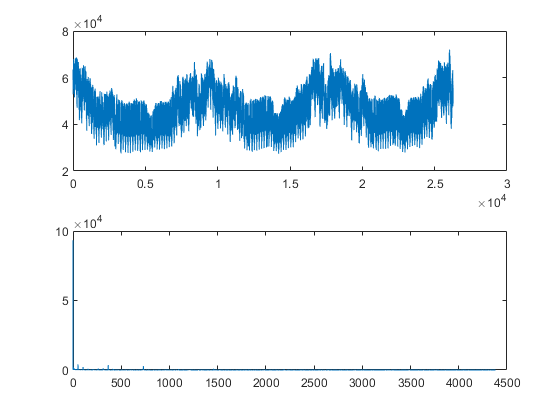

%% TD1---------------------------------------------------------------------
close all; %ferme toutes les fenetres
clear all; %efface toutes les variables

% LOAD SIGNAL
load consoelq.mat;

fe = 24*365; %cycles par années

% ANALYSE
[S,k]=spectre4(ce(1,:), fe);

% AFFICHAGE 
figure(1);
subplot(2,1,1);
plot(ce);
subplot(2,1,2);
plot(k,S);

%% TD 2 -------------------------------------------------------------------
close all; %ferme toutes les fenetres
clear all; %efface toutes les variables

% LOAD SIGNAL
load consoelq.mat;

% VARIABLES
N   = 700;
fen = hamming(N+1);
fe  = 24*365; %cycles par années
f1  = 17/fe;
f2  = 175/fe;

% ANALYSE
[S,k] = spectre4(ce(1,:), fe);

% AFFICHAGE SIGNAL TEMPOREL
figure(1);
subplot(2,1,1);
plot(ce);
subplot(2,1,2);
plot(k,S);

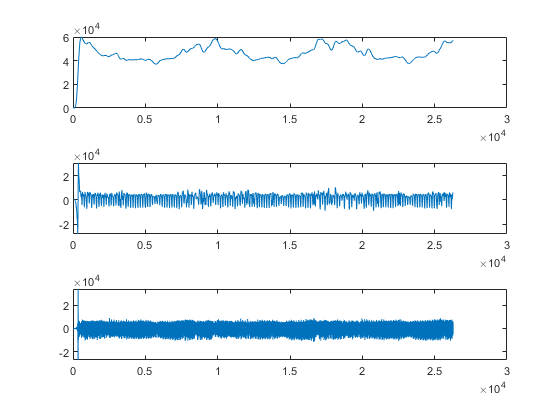


% COMPUTE FILTRE
b_passe_bas   = fir1(N, 2*f1, fen);
b_passe_bande = fir1(N, 2*[f1 f2], fen);
b_passe_haut  = fir1(N, 2*f2, 'high',  fen);

% APPLIQUE FILTRE 
cycle_year  = filter(b_passe_bas,   1, ce);
cycle_month = filter(b_passe_bande, 1, ce);
cycle_day   = filter(b_passe_haut,  1, ce);

% AFFICHE SIGNALE FILTRE TEMP
figure(2);
subplot(3,1,1);
plot(cycle_year);
subplot(3,1,2);
plot(cycle_month);
subplot(3,1,3);
plot(cycle_day);

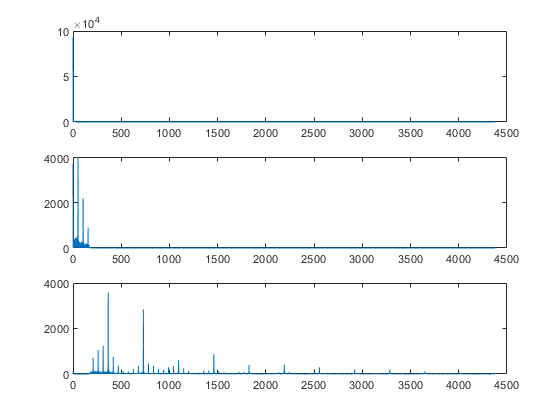


% ANALYSE SIGNAL FILTRE 
[S_year,  k] = spectre4(cycle_year, fe);
[S_month, k] = spectre4(cycle_month, fe);
[S_day,   k] = spectre4(cycle_day, fe);

%AFFICHE SPECTRE SIGNAL FITREE 
figure(3);
subplot(3,1,1);
plot(k, S_year);
subplot(3,1,2);
plot(k, S_month);
subplot(3,1,3);
plot(k, S_day);


%% TD3---------------------------------------------------------------------

